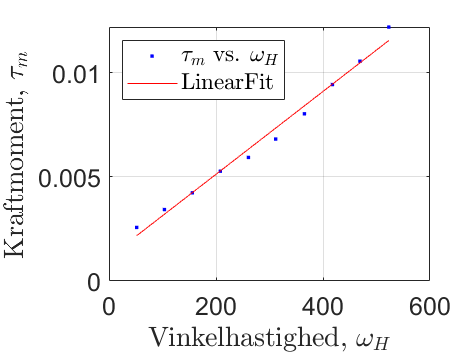

i=1;
data = csvread('B_H\500.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\1000.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\1500.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\2000.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\2500.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\3000.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\3500.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\4000.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\4500.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;
data = csvread('B_H\5000.csv');
current(i) = mean(data(:,2));
RPM(i) = mean(data(:,3));
i=i+1;

rpm2rad = (2*pi)/60;
k_t = 0.0335;
hastighed = (RPM*rpm2rad);
tau_m = (current * k_t);

% plot(RPM, current, '*')
% plot(RPM*rpm2rad, current * k_t, '*')

ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit(hastighed', tau_m', ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, hastighed, tau_m);
legend( h, '$\tau_m$ vs. $\omega_H$', 'LinearFit', 'Location', 'NorthWest', 'Interpreter', 'latex' );
% Label axes
set(gca,'FontSize', 15)
xlabel( 'Vinkelhastighed, $\omega_H$', 'Interpreter', 'latex');
ylabel( 'Kraftmoment, $\tau_m$', 'Interpreter', 'latex' );
grid on